## Метод разложения в ряд Фурье

Круглый диэлектрический цилиндр, E-поляризаци

Метод разложения в ряд Фурье

22-03-21

close all;
clear variables;

### 1. Входные данные

%%  1 - входные данные  
% Параметры среды-1
e1 = 2.56;
mu1 = 1;
k1 = 2*pi*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1); 

% Параметры среды-2
k2 = 2*pi;
eta2 = 120*pi;

% Параметры программы
% a = 5/(2*pi);  % радиус круга 
N_harm = 150; % количество гармоник
% N_circl = 600; % количество точек на круга 
phi_i_grad = 0; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]


mass_a = 0.3 : 0.005 : 1;
for s = 1 : length(mass_a)
    a = mass_a(s)
    N_circl = round(2*pi*a)*100;

a = 0.3000

a = 0.3050

a = 0.3100

a = 0.3150

a = 0.3200

a = 0.3250

a = 0.3300

a = 0.3350

a = 0.3400

a = 0.3450

a = 0.3500

a = 0.3550

a = 0.3600

a = 0.3650

a = 0.3700

a = 0.3750

a = 0.3800

a = 0.3850

a = 0.3900

a = 0.3950

a = 0.4000

a = 0.4050

a = 0.4100

a = 0.4150

a = 0.4200

a = 0.4250

a = 0.4300

a = 0.4350

a = 0.4400

a = 0.4450

a = 0.4500

a = 0.4550

a = 0.4600

a = 0.4650

a = 0.4700

a = 0.4750

a = 0.4800

a = 0.4850

a = 0.4900

a = 0.4950

a = 0.5000

a = 0.5050

a = 0.5100

a = 0.5150

a = 0.5200

a = 0.5250

a = 0.5300

a = 0.5350

a = 0.5400

a = 0.5450

a = 0.5500

a = 0.5550

a = 0.5600

a = 0.5650

a = 0.5700

a = 0.5750

a = 0.5800

a = 0.5850

a = 0.5900

a = 0.5950

a = 0.6000

a = 0.6050

a = 0.6100

a = 0.6150

a = 0.6200

a = 0.6250

a = 0.6300

a = 0.6350

a = 0.6400

a = 0.6450

a = 0.6500

a = 0.6550

a = 0.6600

a = 0.6650

a = 0.6700

a = 0.6750

a = 0.6800

a = 0.6850

a = 0.6900

a = 0.6950

a = 0.7000

a = 0.7050

a = 0.7100

a = 0.7150

a = 0.7200

a = 0.7250

a = 0.7300

a = 0.7350

a = 0.7400

a = 0.7450

a = 0.7500

a = 0.7550

a = 0.7600

a = 0.7650

a = 0.7700

a = 0.7750

a = 0.7800

a = 0.7850

a = 0.7900

a = 0.7950

a = 0.8000

a = 0.8050

a = 0.8100

a = 0.8150

a = 0.8200

a = 0.8250

a = 0.8300

a = 0.8350

a = 0.8400

a = 0.8450

a = 0.8500

a = 0.8550

a = 0.8600

a = 0.8650

a = 0.8700

a = 0.8750

a = 0.8800

a = 0.8850

a = 0.8900

a = 0.8950

a = 0.9000

a = 0.9050

a = 0.9100

a = 0.9150

a = 0.9200

a = 0.9250

a = 0.9300

a = 0.9350

a = 0.9400

a = 0.9450

a = 0.9500

a = 0.9550

a = 0.9600

a = 0.9650

a = 0.9700

a = 0.9750

a = 0.9800

a = 0.9850

a = 0.9900

a = 0.9950

a = 1

## ЭПР

    RCS = zeros(721,1);
    phi_rad_for_graf_DA = zeros(721,1);
    phi_grad_for_graf_DA = zeros(721,1);
    
    for p = 1 
        Sum_E = 0;
        curr_phi_grad = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
        curr_phi_rad = 2*pi/360*curr_phi_grad;
        
        % запищем в массивы для дальнейшего использования
        phi_grad_for_graf_DA(p) = curr_phi_grad; % угол для графика
        phi_rad_for_graf_DA(p) = curr_phi_rad;
        
        for n = -N_harm : 1 : N_harm 
            An = ((-1i)^n)*exp(-1i*n*phi_i_rad);
            Z = -eta1*besselj(n,k1*a)*dH(n,k2*a) + eta2*besselh(n,1,k2*a)*dJ(n,k1*a);
            j2n = 4*An/(a*k2*besselj(n,k2*a)*2*pi) * (-eta1/eta2*besselj(n,k1*a)*dJ(n,k2*a) + dJ(n,k1*a)*besselj(n,k2*a))/Z;
                    
            Sum_E = Sum_E + 2*pi*eta2*k2/4*a*j2n*besselj(n,k2*a)*exp(-1i*n*pi/2)*exp(1i*n*curr_phi_rad);      
        end
        
        RCS = 10*log10((4/k2)*Sum_E*conj(Sum_E));
    
    end

    RCS_a(s) = RCS;
end

figure;
plot(mass_a, RCS_a,'r-');

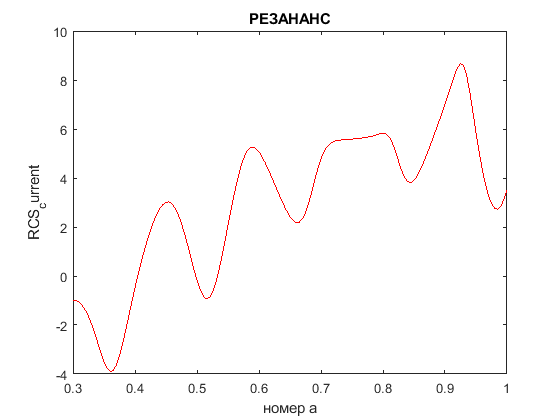

title('РЕЗАНАНС'); 
xlabel('номер а'); 
ylabel('RCS_current');

% name_file = strcat('REZ_FOURIER_Epol_', num2str(length(mass_a)),'.dat');
% f03 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n= 1 : length(mass_a)
%     fprintf(f03,' %10.5f %10.5f\n', mass_a(n), RCS_a(n));
% end
% 
% fclose(f03);

### Используемые функции

function [dJ_calc] = dJ(n,x)
    dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
end
function [dH_calc] = dH(n,x)
    dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
end